clear;
close all;
clc;

ChinID=277;

Load Data

DataRepo='R:\Users\Satya\SP\Codes\SNRenv-OUTPUT\DataAnal\';
dirName=dir([DataRepo '*' num2str(ChinID) '*']);

load([DataRepo dirName(end).name '\SummaryVar.mat']);
SNRcolor='rgb';
SNRs=[-6 0 6];


SNR env vs. Normalized Driven Rate

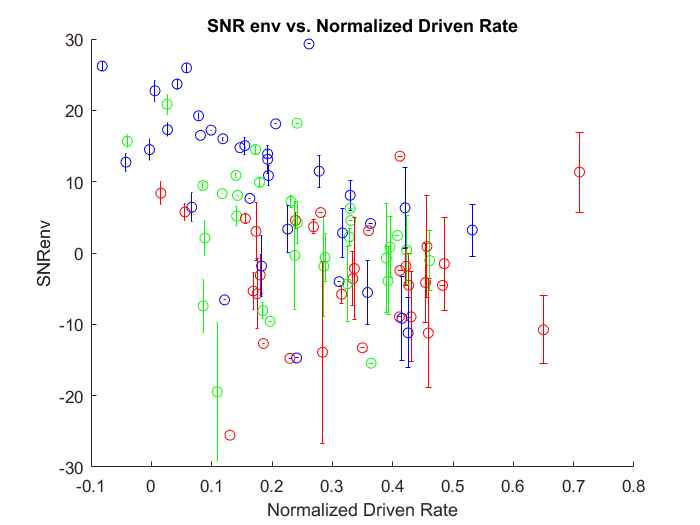

hold on;
for i=1:length(SummaryVar)
    x=(SummaryVar(i).spkRateSN-SummaryVar(i).SR)/(SummaryVar(i).SatR-SummaryVar(i).SR);
    y=SummaryVar(i).SNRenvAll;
    errorbar(x, mean(y), std(y), [SNRcolor(SummaryVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Normalized Driven Rate');
ylabel('SNRenv');
title('SNR env vs. Normalized Driven Rate');

SNR env vs. Driven Rate

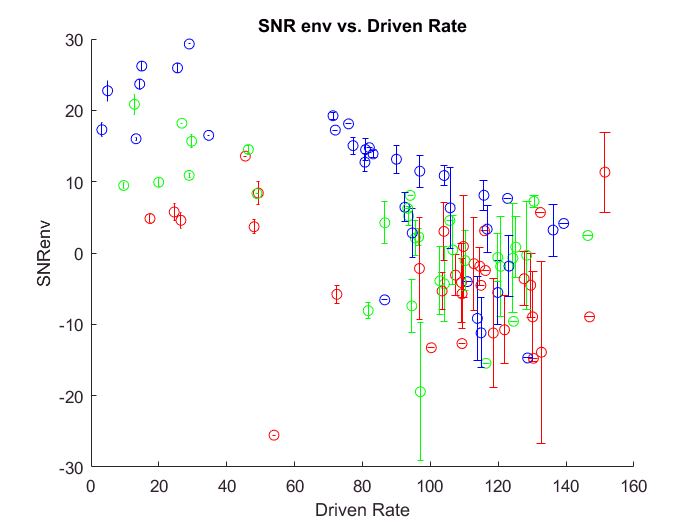

figure;
hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    errorbar(SummaryVar(i).spkRateSN, mean(y), std(y), [SNRcolor(SummaryVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Driven Rate');
ylabel('SNRenv');
title('SNR env vs. Driven Rate');

Revcor Filtered Acoustic SNRenv vs. Neural SNRenv

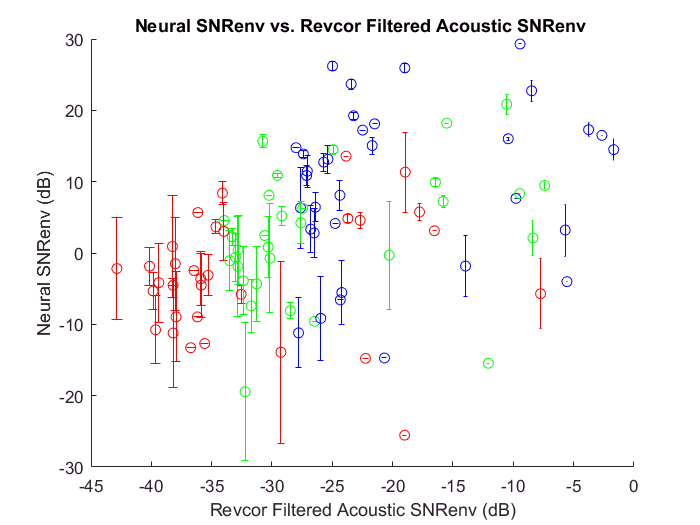

figure;

hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    errorbar(SummaryVar(i).SNRenvACST, mean(y), std(y), [SNRcolor(SummaryVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Revcor Filtered Acoustic SNRenv (dB)');
ylabel('Neural SNRenv (dB)');
title('Neural SNRenv vs. Revcor Filtered Acoustic SNRenv ');

Wiener Filtered Acoustic SNRenv vs. Neural SNRenv

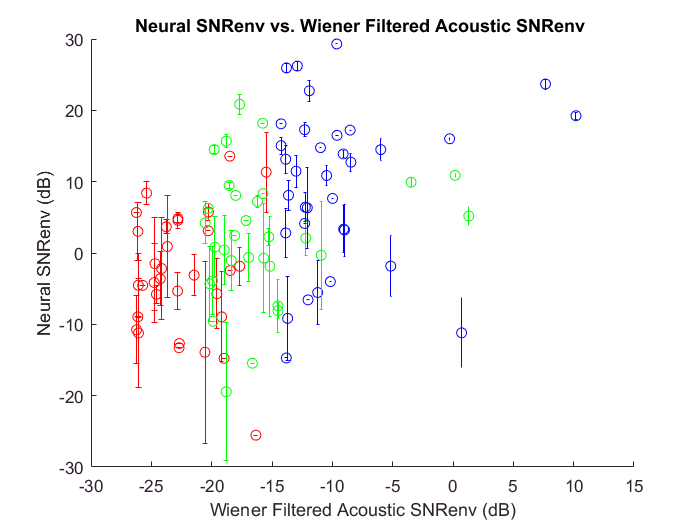

figure;

hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    errorbar(SummaryVar(i).SNRenvACST2, mean(y), std(y), [SNRcolor(SummaryVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Wiener Filtered Acoustic SNRenv (dB)');
ylabel('Neural SNRenv (dB)');
title('Neural SNRenv vs. Wiener Filtered Acoustic SNRenv ');

Tuning Curve BF vs REVCOR BF

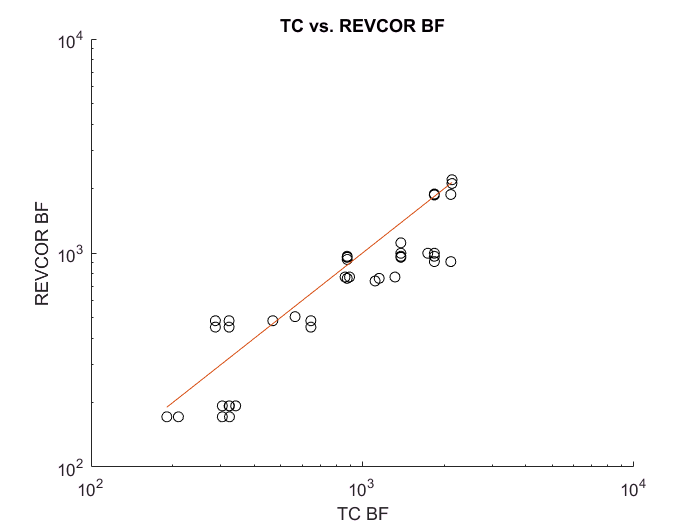

scatter([SummaryVar.BF_TC],[SummaryVar.BF_wiener],'k');
set(gca,'xscale','log','yscale','log');
hold on; 
BF_TC=extractfield(SummaryVar, 'BF_TC');
plot([min(BF_TC) max(BF_TC)], [min(BF_TC) max(BF_TC)]);
xlabel('TC BF');
ylabel('REVCOR BF');
title('TC vs. REVCOR BF');

SNRenv vs CF

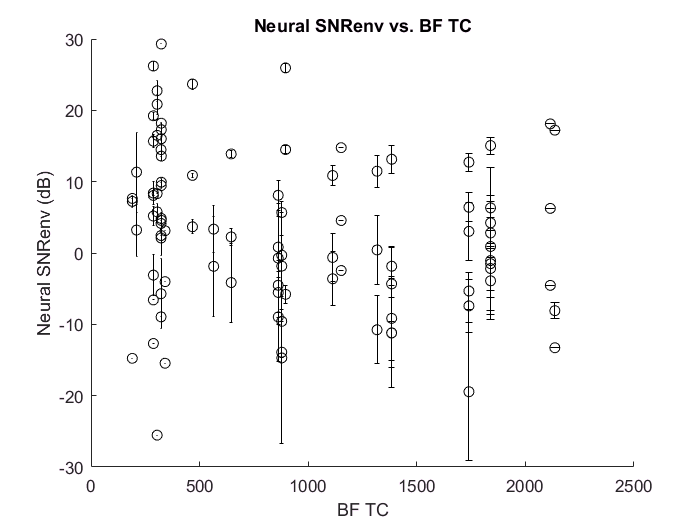

figure;
hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    errorbar(SummaryVar(i).BF_TC, mean(y), std(y), 'ko');
end
hold off;
xlabel('BF TC');
ylabel('Neural SNRenv (dB)');
title('Neural SNRenv vs. BF TC');

SNRenv vs. Total Spike for computing SNRenv

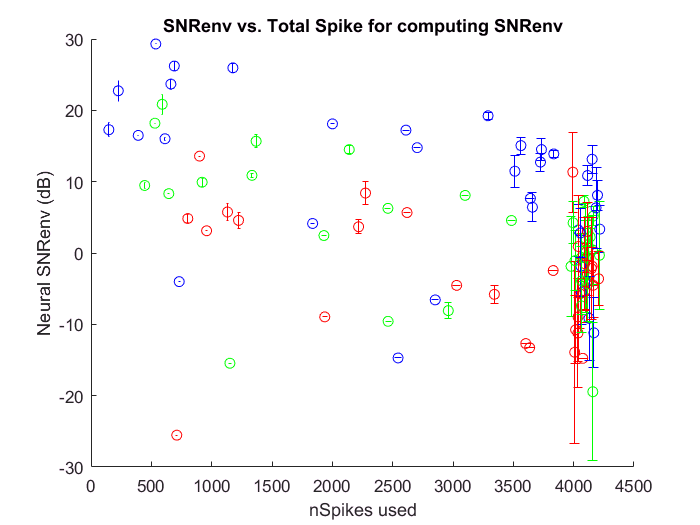

figure;
hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    errorbar(SummaryVar(i).nSpikesSN, mean(y), std(y), [SNRcolor(SummaryVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('nSpikes used');
ylabel('Neural SNRenv (dB)');
title('SNRenv vs. Total Spike for computing SNRenv');

SNRenv vs. Q10 from TC

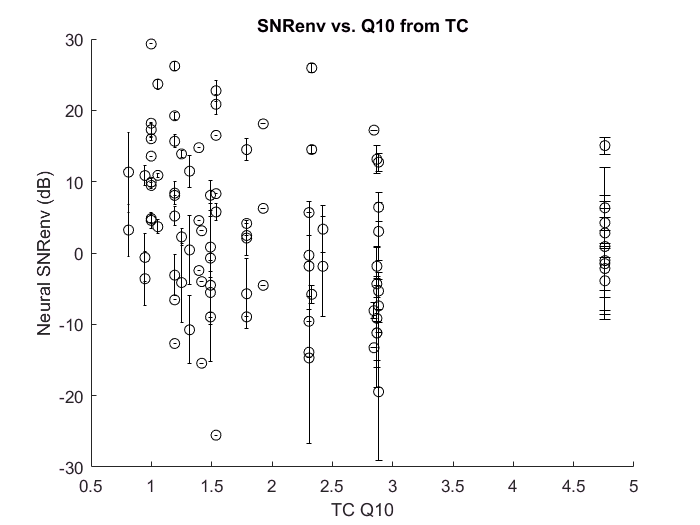

figure;
hold on;
for i=1:length(SummaryVar)
    y=SummaryVar(i).SNRenvAll;
    if SummaryVar(i).Q10_TC<25
        errorbar(SummaryVar(i).Q10_TC, mean(y), std(y), 'ko');
    end
end
hold off;
xlabel('TC Q10');
ylabel('Neural SNRenv (dB)');
title('SNRenv vs. Q10 from TC');